# SignalTrace

**Overview**

The `SignalTrace` chart organizes the vertical display of multiple signal channels. The chart data comprises a numeric vector `Time` and a numeric matrix `SignalData`. Each column of `SignalData` is interpreted as a separate channel. To organize the vertical display of the signals, the chart normalizes each channel to have zero mean and unit standard deviation, then plots each signal against time in a vertical stack, leaving a small gap between each successive pair of signals. Signals may be inserted or removed from the chart by modifying the `SignalData` property. The time vector is changed by modifying the `Time` property.

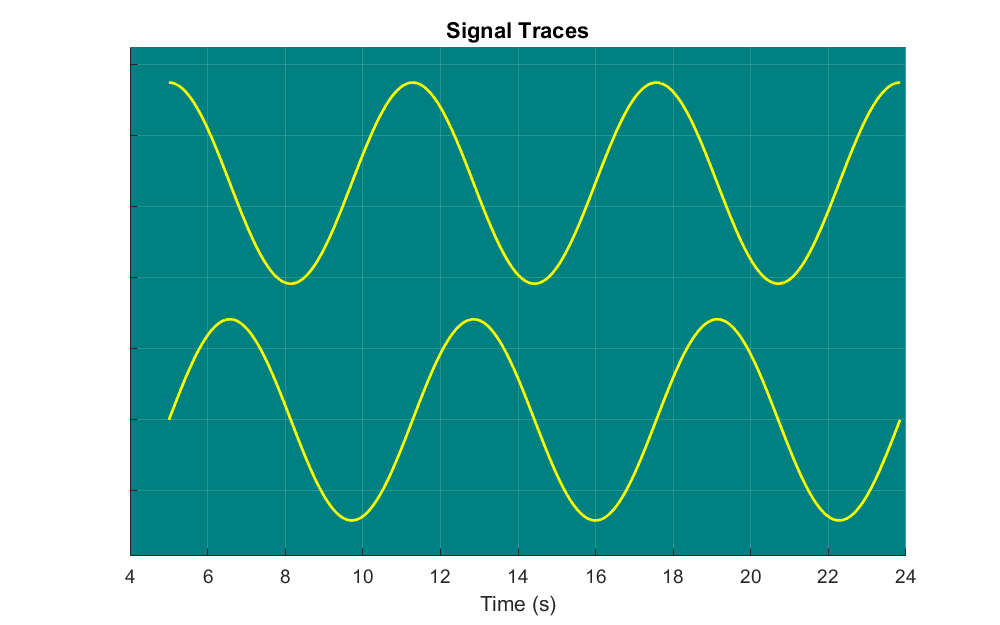

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'SignalTrace.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'SignalTrace'))) the source code for the `SignalTrace` chart.

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.SignalTrace

## Create data for the chart: time and signals.

First, define a time vector from 0 to $6\pi$containing 5000 elements.

t = linspace( 0, 6 * pi, 5000 ).';

Next, define various signals:

- $y_1$ is a discrete signal taking values $0$, $-1$ and $1$;

- $y_2$ is a sine wave;

- $y_3$ is a cosine wave;

- $y_4$ is the product of a sine wave and a cosine wave which have different frequencies.

y1 = [zeros( 1000, 1 ); ones( 500, 1 );
      zeros( 500, 1 ); (-1) * ones( 500, 1 );
      ones( 1000, 1 ); zeros( 1000, 1 ); 
      ones( 500, 1 )];
y2 = sin( t );
y3 = cos( t );
y4 = 2 * sin( 2 * t ) .* cos( 3 * t );

Join the signals $y_1$, $y_2$, $y_3$ and $y_4$ into a matrix with four columns.

signals = [y1, y2, y3, y4];

## Create a figure for the chart.

f = galleryFigure( 'Name', 'SignalTrace Example' );    

## Create the chart.

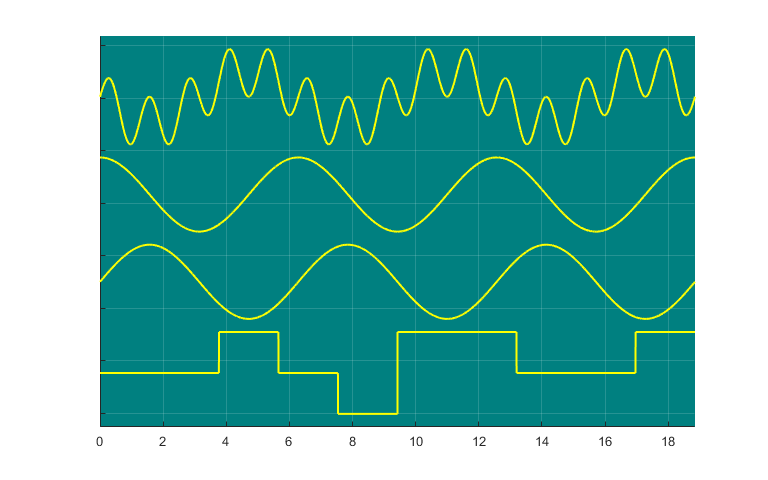

ST = SignalTrace( 'Parent', f, ...
                  'Time', t, ...
                  'SignalData', signals );

## Customize the chart appearance.

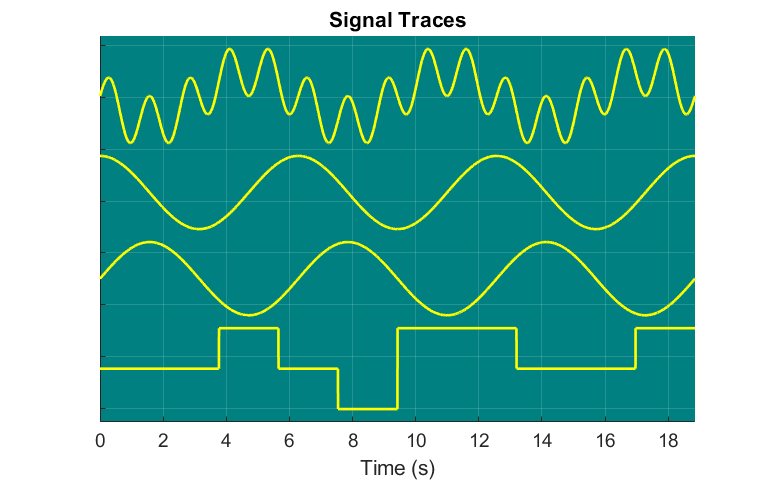

ST.XLabel.String = 'Time (s)';
ST.XLabel.FontSize = 14;
ST.Title.String = 'Signal Traces';
ST.Title.FontSize = 16;
ST.XAxis.FontSize = 14;
ST.SignalLineWidth = 2;

## Change the chart data.

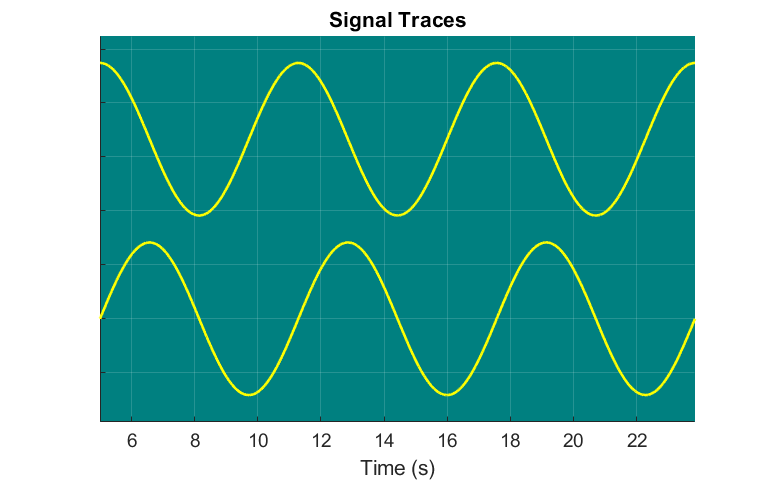

ST.Time = 5 + ST.Time;
ST.SignalData = [y2, y3];